clear all
close all
clc

% transmittion mechanic
mech.L = 0.5;
mech.l = 0.03;
mech.h = 0.25;
mech.H = 0.2270;
mech.hp = 0.023;

% physics constants
const.g = 9.80665;
const.rad2deg = 180/pi;
const.deg2rad = 1/const.rad2deg;

% H bridge motor drive
driver.kc = 1;
driver.Tc = 2e-9;

% DC stepper motor
stepper.La = 1.6e-3;
stepper.Ra = 2.5;
stepper.Km = 0.18;
stepper.tausf = 0;
stepper.Jeq = 5.5e-6;
stepper.Beq = 2.5e-9;
stepper.Nr = 100;
stepper.p = 2;
stepper.pp = stepper.Nr/stepper.p;
stepper.precision = 360/(stepper.p*stepper.Nr);
stepper.precision2 = stepper.precision/2;

stepper.Tstep = 2e-3;

% arduino
arduino.arch = 8;
arduino.vcc = 5;
arduino.gnd = 0;
arduino.adc.n_bits = 10;
arduino.adc.q_step = (arduino.vcc - arduino.gnd)/(2^(arduino.adc.n_bits));
arduino.adc.fc = 9615;

% ball
ball.m = 0.0029;
ball.r = 0.02;
ball.I = 2/3*ball.m*ball.r*ball.r;

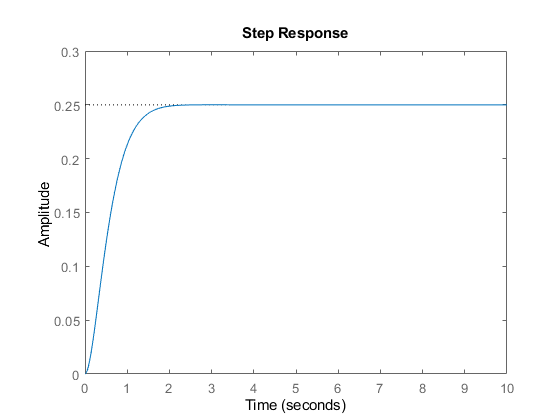

request.Mp = 0.05;
request.ts = 3;
ballnbeam.controller.Tc = 20e-3;
ballnbeam.A = [0 1; 0 0];
ballnbeam.b = [0;-const.g*(mech.l/mech.L)*(ball.r*ball.r/(ball.I+ball.r*ball.r*ball.m))];
ballnbeam.C = [1 0];
ballnbeam.d = 0;

sys = ss(ballnbeam.A, ballnbeam.b, ballnbeam.C, ballnbeam.d);

gains = [ballnbeam.A ballnbeam.b; ballnbeam.C ballnbeam.d]\[0;0;1];

ballnbeam.controller.Nx = [gains(1,1);gains(2,1)];
ballnbeam.controller.Nu = gains(3,1);

delta = log(1/request.Mp)/sqrt(pi^2 + log(1/request.Mp)^2);
wn    = 3/(delta*request.ts);

p1    = -3*delta*wn + 1i*wn*sqrt(1-delta^2);
p2    = conj(p1);
ballnbeam.controller.K = -place(ballnbeam.A, ballnbeam.b, [p1 p2]);
ballnbeam.controller.Nbar = -(ballnbeam.controller.Nu+ballnbeam.controller.K*ballnbeam.controller.Nx);
stable_sys = ss(ballnbeam.A+ballnbeam.b*ballnbeam.controller.K,ballnbeam.b,ballnbeam.C,ballnbeam.d);
step(0.25*ballnbeam.controller.Nbar*stable_sys,10)

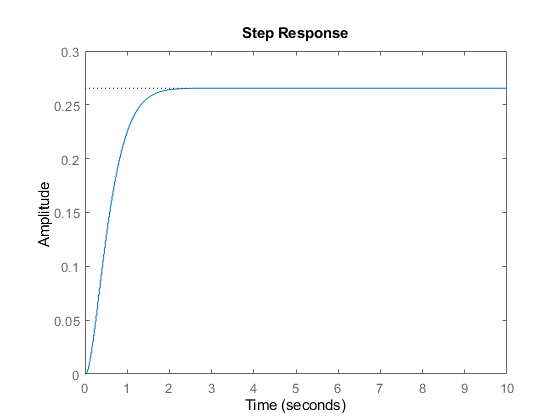

%% Digital
sysd = c2d(sys, ballnbeam.controller.Tc, 'zoh');
ballnbeam.Ad = sysd.A;
ballnbeam.bd = sysd.B;
ballnbeam.Cd = sysd.C;
ballnbeam.dd = sysd.D;
p1d = exp(p1*ballnbeam.controller.Tc);
p2d = exp(p2*ballnbeam.controller.Tc);
ballnbeam.controller.Kd = -place(ballnbeam.Ad, ballnbeam.bd, [p1d p2d]);
stable_sysd = ss(ballnbeam.Ad+ballnbeam.bd*ballnbeam.controller.Kd,ballnbeam.bd,ballnbeam.Cd,ballnbeam.dd, ballnbeam.controller.Tc);
step(0.25*ballnbeam.controller.Nbar*stable_sysd,10)

%% Filter
% signal
fc = 2;
phi = pi / 2;
mu = 2 * pi * fc;

% noise
fc_noise = 1/ballnbeam.controller.Tc;
phi_noise = pi / 2 * 0.1;
mu_noise = 2 * pi * fc_noise;

% data creation
t = 0:0.00001:1;
u = sin(mu * t + phi);
e0 = sin(mu_noise * t + phi_noise);
y = u + e0;

td = 0:0.00001:1;
ud = sin(mu * td + phi);
e0d = sin(mu_noise * td + phi_noise);
yd = ud + e0d;

% filtering
mu0 = mu;
s = tf('s');
H = mu0 / ( s + mu0 );
y_hat = lsim(H, y, t);

Hd = c2d(H, 0.00001, 'zoh');
Hd

Hd =
 
  0.0001257
  ----------
  z - 0.9999
 
Sample time: 1e-05 seconds
Discrete-time transfer function.



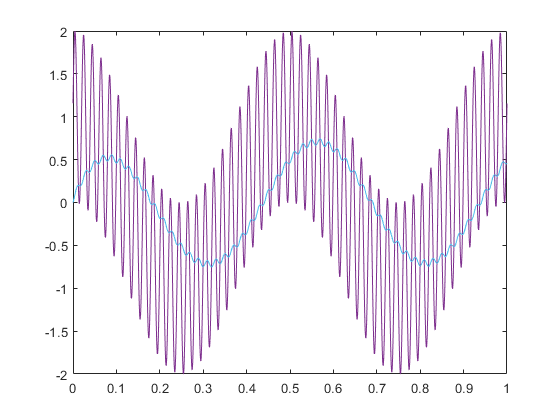

yd_hat = lsim(Hd, yd, td);

plot(t, y)
hold on
plot(t, y_hat)
plot(td, yd_hat)

[ballnbeam.filter.num, ballnbeam.filter.den] = tfdata(Hd);
ballnbeam.filter.num = cell2mat(ballnbeam.filter.num);
ballnbeam.filter.den = cell2mat(ballnbeam.filter.den);

%% Integral Action
ballnbeam.Ae = [0 ballnbeam.C;[0;0] ballnbeam.A];
ballnbeam.Be = [0;ballnbeam.b];

sigma = -delta*wn;
wd = wn*sqrt(1-delta^2);

poles = [2*sigma + 1i*wd, 2*sigma - 1i*wd, 2*sigma];

Ke = -place(ballnbeam.Ae,ballnbeam.Be,poles);
ballnbeam.controller.Ki = Ke(1);
ballnbeam.controller.Ke = Ke(1,2:3);

function [wgc, phim] = getWgcPhim(Mp, ts)
    delta = log(1/Mp)/sqrt(pi^2+log(1/Mp)^2);
    wgc = 3/delta/ts;
    phim = 180/pi*atan(2*delta/sqrt(sqrt(1+4*delta^4)-2*delta^2));
end

function [Kp,Ki,Kd] = getPIDBodeFreq(plant, freq, phim, alpha)
    wgc = 2*pi*freq;
    [Kp,Ki,Kd] = getPIDBode(plant, wgc, phim, alpha);
end

function [Kp,Ki,Kd] = getPIDBode(plant, wgc, phim, alpha)
    [mag, phase] = bode(plant, wgc);
    DeltaK = 1 / mag;
    DeltaPhi = -180 + phim - phase;
    tmp = tand(DeltaPhi);
    Td = (tmp + sqrt(tmp^2 + 4/alpha))/(2*wgc);
    Ti = alpha * Td;
    Kp = DeltaK * cosd(DeltaPhi);
    Ki = Kp / Ti;
    Kd = Kp * Td;
    s = tf('s');
    C = Kp + Ki * (1/s) + Kd * s;
    [a,b,c,d] = margin(C*plant);
    delta_wgc = d - wgc;
    delta_phim = b - phim;
    assert(delta_wgc < 0.01, "failed to build PID");
    assert(delta_phim < 0.01, "failed to build PID");
end